# Cartographie bathymétrie

## Génération d'une carte aléatoire

clear all;
clf;
clc;

## Génération de la carte

On peut générer une carte aléatoirement suivant différents paramètres, la profondeur, la hauteur, le coefficient de Hurtz et l'écart type.

 
clf;
p = 20;H = 1;s = 0.5; lx = 2^8; c=0.2;

La carte des iso-surfaces, reconstruit en 3D :

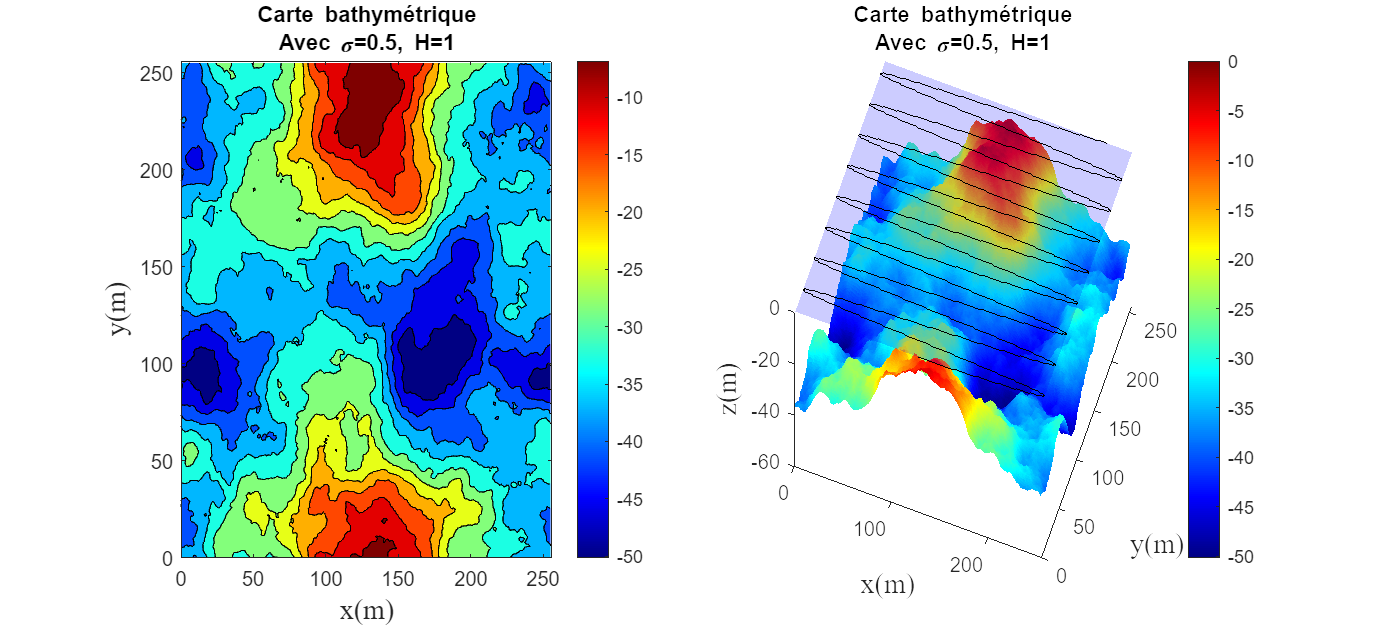

% Génération de la trajectoire
t = [0:0.1:lx];
x = round(lx/2*sin(c*t)+lx/2); x(x==0) = 1;
y = round(t); y(y==0) = 1;

MAP = carte(s,H,10,lx,lx,p,-10);
figure('Renderer', 'painters', 'Position', [10 10 2000 900]);
hold all
subplot(121);
contourf([0:1:lx-1],[0:1:lx-1],MAP,10);
ylim([0, lx]);
xlim([0, lx]);
xlabel('x(m)','FontName','Times','FontSize',14)
ylabel('y(m)','FontName','Times','FontSize',14)
zlabel('z(m)','FontName','Times','FontSize',14)
colorbar();
colormap('jet');
% contourf(MAP*0,'EdgeColor','none','FaceAlpha',0.3,'FaceColor','blue');
title({'Carte bathymétrique',['Avec \sigma=',num2str(s),', H=',num2str(H)]});

subplot(122);
hold all
plot(x,y,'LineWidth',0.5,'Color','black');
surf([0:1:lx-1],[0:1:lx-1],MAP,'EdgeColor','none');
surf(MAP*0,'EdgeColor','none','FaceColor','blue',FaceAlpha=0.2);
ylim([0, lx]);
xlim([0, lx]);
xlabel('x(m)','FontName','Times','FontSize',14)
ylabel('y(m)','FontName','Times','FontSize',14)
zlabel('z(m)','FontName','Times','FontSize',14)
colorbar();
colormap('jet');
% contourf(MAP*0,'EdgeColor','none','FaceAlpha',0.3,'FaceColor','blue');
title({'Carte bathymétrique',['Avec \sigma=',num2str(s),', H=',num2str(H)]});
view([20, 60]);


z = [];
for i=1:length(x)
    z = [z MAP(x(i),y(i))+rand(1)/2];
end


### Relevé bathymétrique

On récupère la profondeur via le sonar suivant les coordonnées du navire. On a un petit bruit de mesure sur les données bathymétriques.

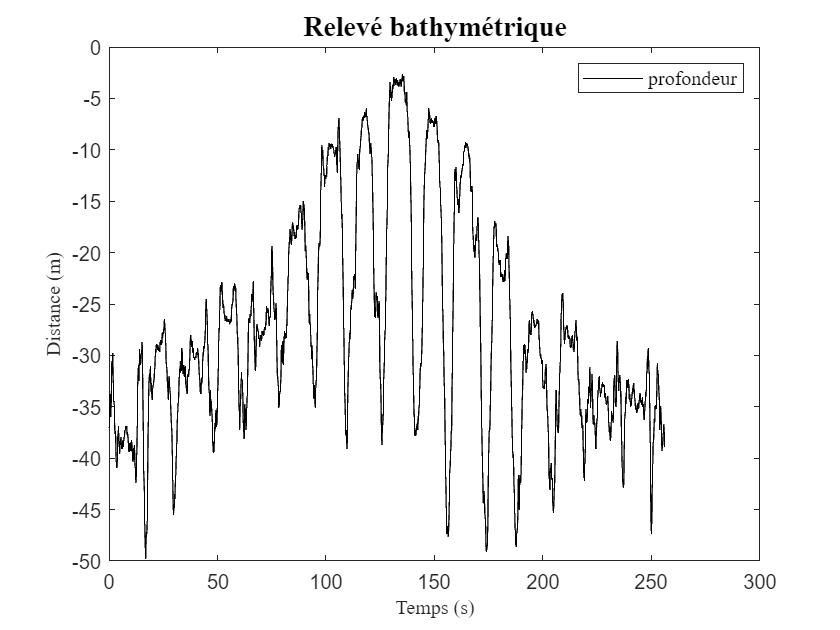

clf
figure()
plot(t,z,'LineWidth',1,'Color','black','LineWidth',0.5);
legend({'profondeur'},'FontName','Times','FontSize',10);
title({'Relevé bathymétrique'},'FontName','Times','FontSize',14);
xlabel({'Temps (s)'},'FontName','Times','FontSize',10);
ylabel({'Distance (m)'},'FontName','Times','FontSize',10);

Soit le relevé bathymétrique suivant :

clf
figure('Renderer', 'painters', 'Position', [10 10 1200 1200]);
[xq,yq] = meshgrid([0:1:lx-1], [0:1:lx-1]);
hold all
vq = griddata(x,y,z,xq,yq,'cubic');

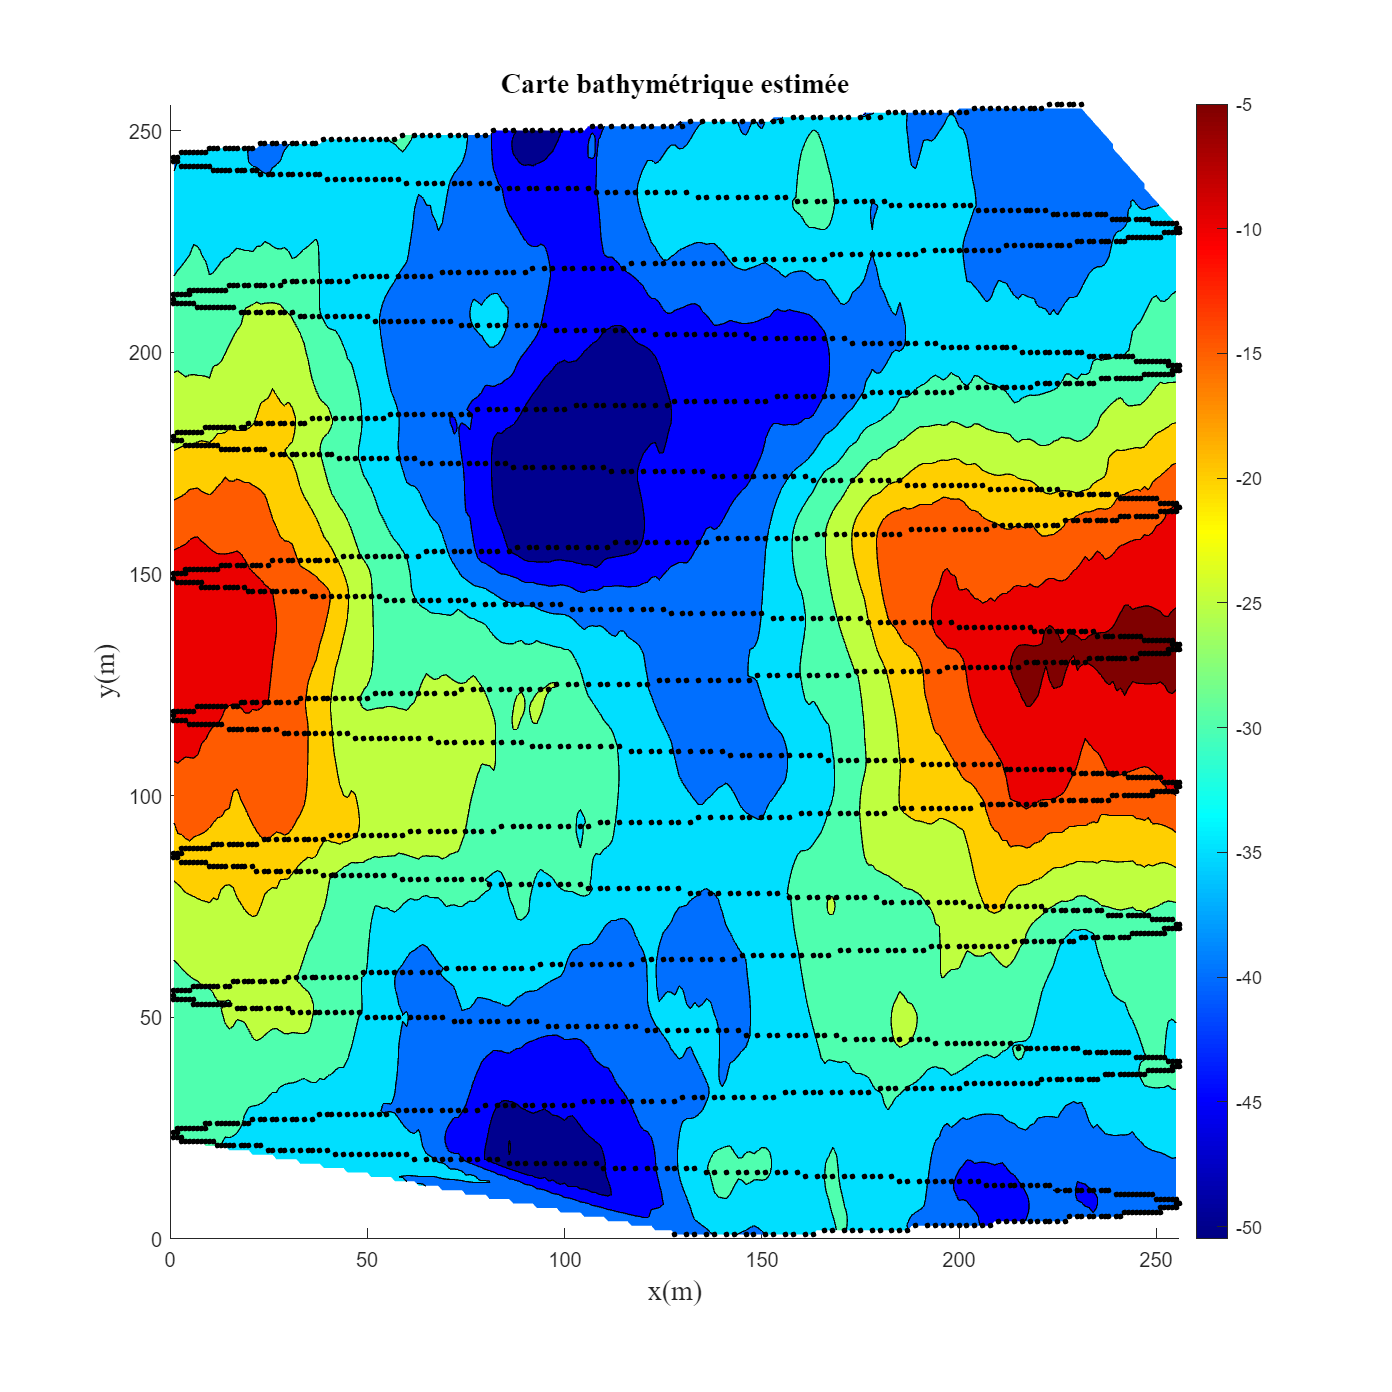

contourf(xq,yq,vq);
colormap('jet');
colorbar();
scatter(x(:),y(:),8,'filled','MarkerEdgeColor','none','MarkerFaceColor','black');
xlabel('x(m)','FontName','Times','FontSize',14);
ylabel('y(m)','FontName','Times','FontSize',14);
zlabel('z(m)','FontName','Times','FontSize',14);
title({'Carte bathymétrique estimée'},'FontName','Times','FontSize',14);
ylim([0, lx]);
xlim([0, lx]);


clf
figure('Renderer', 'painters', 'Position', [10 10 2000 900])
subplot(1,2,1)
[xq,yq] = meshgrid([0:1:lx-1], [0:1:lx-1]);
vq = griddata(x,y,z,xq,yq,"cubic");

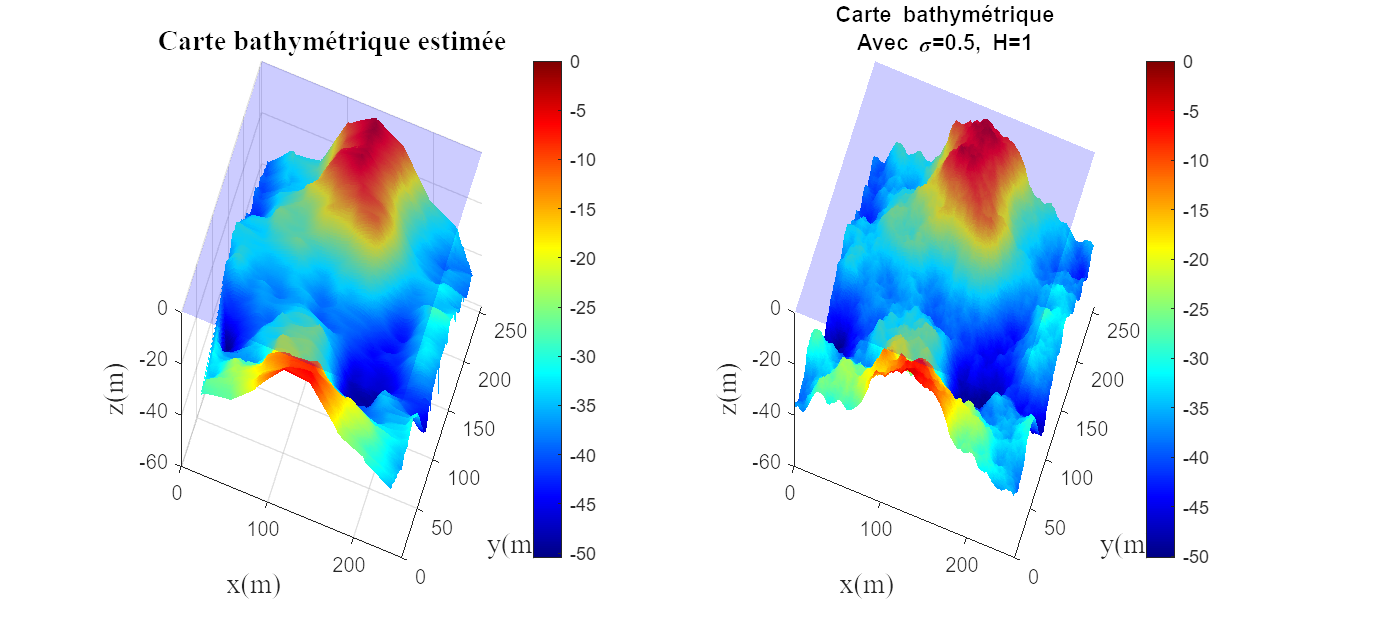

surf(xq,yq,vq','EdgeColor','none');
hold on
surf(MAP*0,'EdgeColor','none','FaceColor','blue',FaceAlpha=0.2);
colorbar();
hold on
xlabel('x(m)','FontName','Times','FontSize',14);
ylabel('y(m)','FontName','Times','FontSize',14);
zlabel('z(m)','FontName','Times','FontSize',14);
title({'Carte bathymétrique estimée'},'FontName','Times','FontSize',14);
ylim([0, lx]);
xlim([0, lx]);
view([20, 60]);

subplot(1,2,2)
hold all
surf([0:1:lx-1],[0:1:lx-1],MAP,'EdgeColor','none');
surf(MAP*0,'EdgeColor','none','FaceColor','blue',FaceAlpha=0.2);
ylim([0, lx]);
xlim([0, lx]);
xlabel('x(m)','FontName','Times','FontSize',14)
ylabel('y(m)','FontName','Times','FontSize',14)
zlabel('z(m)','FontName','Times','FontSize',14)
colorbar();
colormap('jet');
% contourf(MAP*0,'EdgeColor','none','FaceAlpha',0.3,'FaceColor','blue');
title({'Carte bathymétrique',['Avec \sigma=',num2str(s),', H=',num2str(H)]});
view([20, 60]);

### Les erreurs

On a quelques erreurs dus aux bruits du sonar et l'erreur sur la position en x,y et z du navire. On a donc la carte des erreurs suivantes :

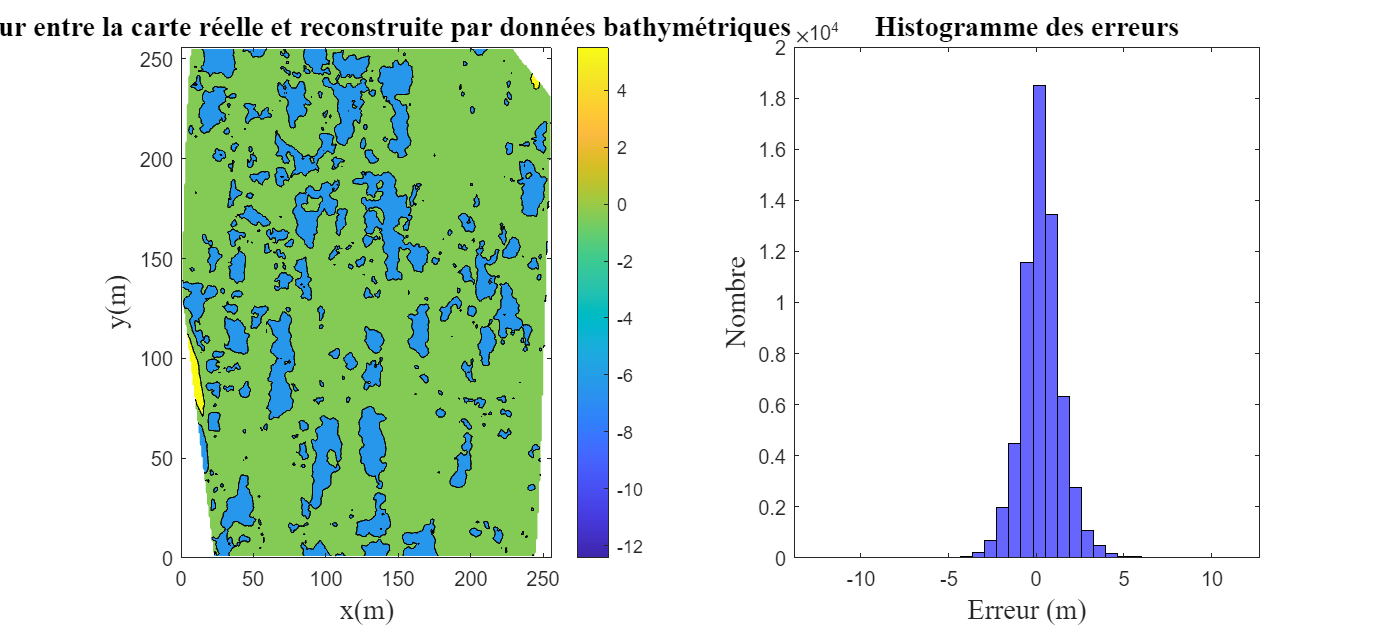

clf
figure('Renderer', 'painters', 'Position', [10 10 2000 900]);
subplot(1,2,1);
err = vq'-MAP;
contourf(xq,yq,err,3);
colorbar();
hold on
xlabel('x(m)','FontName','Times','FontSize',14);
ylabel('y(m)','FontName','Times','FontSize',14);
zlabel('z(m)','FontName','Times','FontSize',14);
title({'Erreur entre la carte réelle et reconstruite par données bathymétriques'},'FontName','Times','FontSize',14);
ylim([0, lx]);
xlim([0, lx]);
subplot(1,2,2);
histogram(err(:)',35,'FaceColor','blue')
title({'Histogramme des erreurs'},'FontName','Times','FontSize',14);
xlabel('Erreur (m)','FontName','Times','FontSize',14);
ylabel('Nombre','FontName','Times','FontSize',14);